Valid positions (Xc, Yc, theta1, theta2, theta3):


 -160.0000  123.0000    1.8935    2.9283   -1.8979
 -160.0000  123.0000    1.6697    2.8242   -2.8068
 -160.0000  124.0000    1.9965    2.9099   -1.8968
 -160.0000  124.0000    1.5565    2.8361   -2.8134
 -160.0000  125.0000    2.0591    2.8705   -1.8957
 -160.0000  125.0000    1.4843    2.8691   -2.8200
 -159.0000  123.0000    1.8284    2.9627   -1.8913
 -159.0000  123.0000    1.6860    2.7880   -2.8079
 -159.0000  124.0000    1.9564    2.9513   -1.8902
 -159.0000  124.0000    1.5490    2.7929   -2.8145
 -159.0000  125.0000    2.0244    2.9390   -1.8891
 -159.0000  125.0000    1.4725    2.7988   -2.8211
 -159.0000  126.0000    2.0747    2.9251   -1.8881
 -159.0000  126.0000    1.4139    2.8063   -2.8276
 -159.0000  127.0000    2.1155    2.9087   -1.8871
 -159.0000  127.0000    1.3653    2.8163   -2.8341
 -159.0000  128.0000    2.1498    2.8861   -1.8862
 -159.0000  128.0000    1.3235    2.8324   -2.8406
 -158.0000  124.0000    1.9167    2.9770   -1.8836
 -158.0000  124.0000    1.5407 

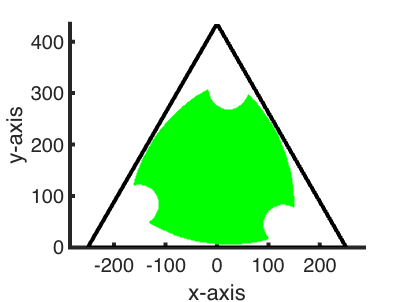

Xc_range = -350:1:350;
Yc_range = -100:1:600; 
alpha = deg2rad(10);
PB = [(-145*sqrt(3)), 0; (145*sqrt(3)), 0; 0, 435];

valid_positions = [];

r = 130;
Sa = 170; 
L = 130; 

for Xc = Xc_range
    for Yc = Yc_range
        [theta, PP] = inverse_kinematics(Xc, Yc, r, alpha, Sa, L, PB);
        if ~isempty(theta) && all(imag(theta(:)) == 0)  % Check both configurations are real
            % Store both configurations if valid
            valid_positions = [valid_positions; Xc, Yc, theta(:, 1)'];  % Elbow-up
            valid_positions = [valid_positions; Xc, Yc, theta(:, 2)'];  % Elbow-down
        end
    end
end

% Plot valid positions
if isempty(valid_positions)
    figure;
    hold on;
    plot([PB(1,1), PB(2,1), PB(3,1), PB(1,1)], ...
         [PB(1,2), PB(2,2), PB(3,2), PB(1,2)], 'k-', 'LineWidth', 4);
    xlabel('x-axis', 'FontSize', 20);
    ylabel('y-axis', 'FontSize', 20);
    set(gca, 'LineWidth', 4, 'FontSize', 20);
    axis equal;

else
    disp('Valid positions (Xc, Yc, theta1, theta2, theta3):');
    disp(valid_positions);

    figure;
    hold on;
    scatter(valid_positions(:,1), valid_positions(:,2), 'g.');
    xlabel('x-axis', 'FontSize', 20);
    ylabel('y-axis', 'FontSize', 20);
    set(gca, 'LineWidth', 4, 'FontSize', 20);
    plot([PB(1,1), PB(2,1), PB(3,1), PB(1,1)], ...
         [PB(1,2), PB(2,2), PB(3,2), PB(1,2)], 'k-', 'LineWidth', 4);
    axis equal;
end